# Nigel - Sim2Real Diffusion Experiments

**Camera:** Ego-centric (FPV) camera images.

**LIDAR:** Ego-centric 2D LIDAR pointcloud data (used for state estimation).

**Vehicle States:** Position and velocity $\left\lbrack \begin{array}{c}
x\\
y\\
v\\
\omega 
\end{array}\right\rbrack$ in SI units.

**Control Inputs:** Throttle and steering$\left\lbrack \begin{array}{c}
\tau \\
\delta \;
\end{array}\right\rbrack$ in SI units.

Clear the workspace.

close all;
clear;
clc;

Load the .bag file using a GUI prompt.

[bag_file,path] = uigetfile('*.bag','multiselect','off');
bag_file = rosbag(strcat(path,bag_file))

bag_file =   BagSelection with properties:

           FilePath: 'C:\Users\csamak\Downloads\Sim2Real Diffusion\sim2real_diffusion_on.bag'
          StartTime: 1.7458e+09
            EndTime: 1.7458e+09
        NumMessages: 16429
    AvailableTopics: [43×3 table]
    AvailableFrames: {8×1 cell}
        MessageList: [16429×4 table]


bag_file.AvailableTopics

ans = 43×3 table
                                                                      NumMessages                 MessageType                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        MessageDefinition              

Select topics of interest.

camera_selection = select(bag_file,'Topic','/camera/color/image_raw');
odometry_selection = select(bag_file,'Topic','/odom');
throttle_selection = select(bag_file,'Topic','/autodrive/nigel_1/throttle_command');
steering_selection = select(bag_file,'Topic','/autodrive/nigel_1/steering_command');

Extract data from messages.

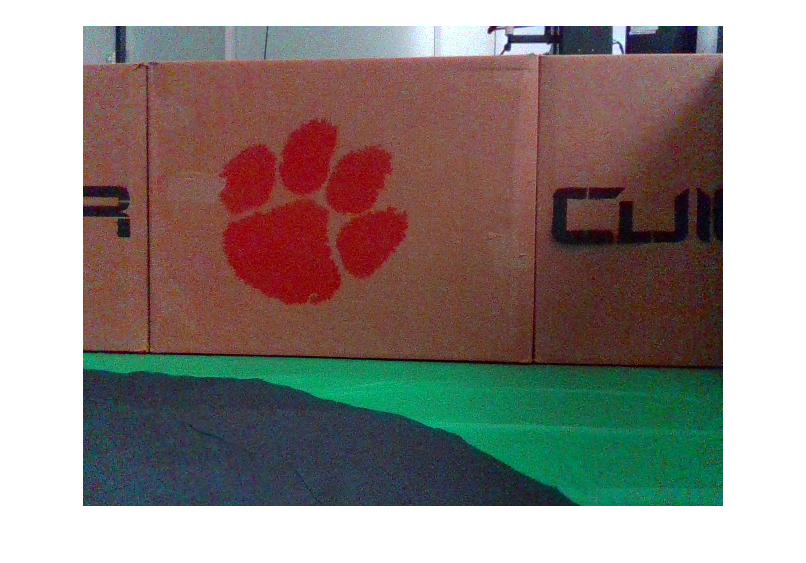

odometry_ts = timeseries(odometry_selection, ...
    'Pose.Pose.Position.X', ...
    'Pose.Pose.Position.Y', ...
    'Twist.Twist.Linear.X');
odometry = odometry_ts.Data;
odometry(:,3) = -odometry(:,3);

throttle_ts = timeseries(throttle_selection,'Data');
throttle = throttle_ts.Data;

steering_ts = timeseries(steering_selection,'Data');
steering = steering_ts.Data;

image_messages = readMessages(camera_selection);
image_data = readImage(image_messages{1});
imshow(image_data);

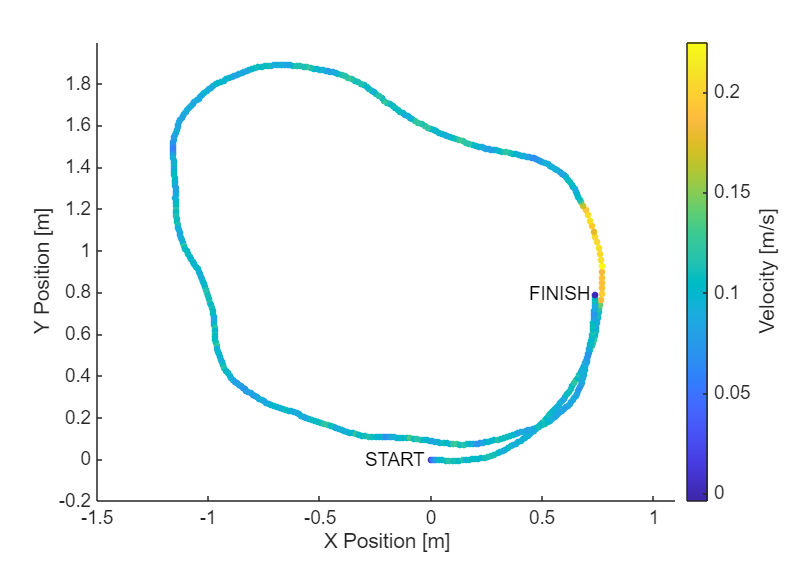

scatter(odometry(:,1),odometry(:,2),25,odometry(:,3),'filled'); % Scaled and shifted scatter plot of vehicle position with 25 point size and velocity-based color-gradient
text(odometry(1,1)-0.3,odometry(1,2),'START','Color','black','FontSize',14);
text(odometry(end,1)-0.3,odometry(end,2),'FINISH','Color','black','FontSize',14);
axis on
xlabel('X Position [m]'); % Define x-axis label
ylabel('Y Position [m]'); % Define y-axis label
xlim([-1.5 1.1]);
ylim([-0.2 2.0]);
set(gca,'FontName','Arial','FontSize',14); % Font for the scatter plot
c = colorbar; % Colorbar instance
caxis([min(odometry(:,3)) max(odometry(:,3))]); % Colorbar limits
c.FontName = 'Arial'; % Font for colorbar
c.FontSize = 14; % Font size for colorbar ticks
c.Label.String = 'Velocity [m/s]'; % Colorbar label
c.Label.FontName = 'Arial'; % Font for colorbar label
c.Label.FontSize = 16; % Font size for colorbar label
colormap(parula) % Colorbar colormap

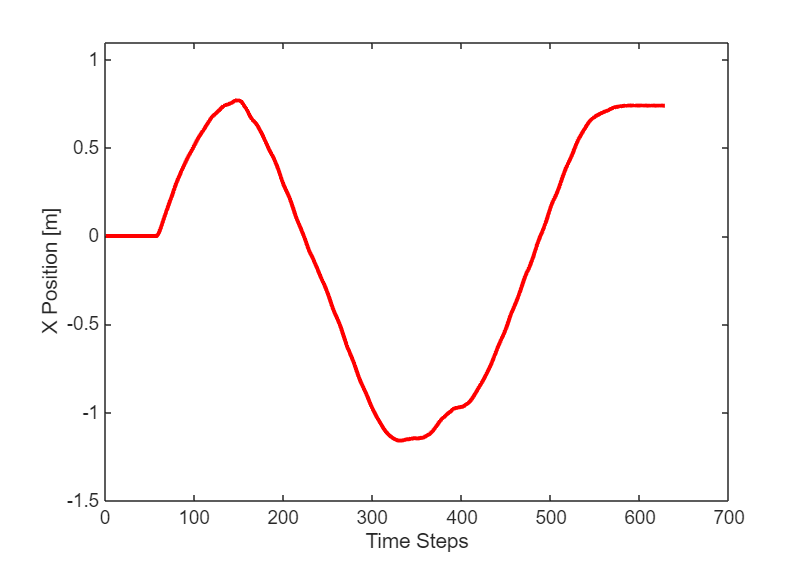

plot(odometry(:,1),'LineWidth',3,'Color','r'); % Plot with 3 line width
axis on
xlabel('Time Steps'); % Define x-axis label
ylabel('X Position [m]'); % Define y-axis label
ylim([-1.5 1.1]);
set(gca,'FontName','Arial','FontSize',14); % Font for the plot

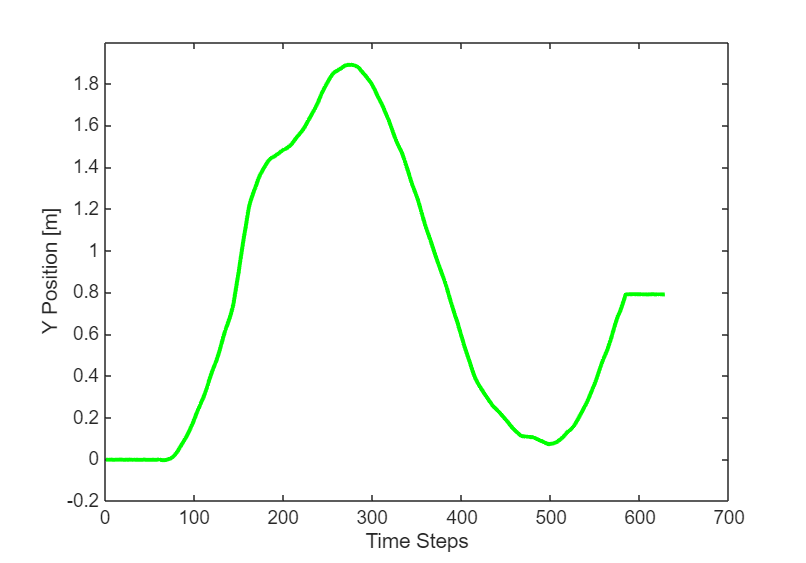

plot(odometry(:,2),'LineWidth',3,'Color','g'); % Plot with 3 line width
axis on
xlabel('Time Steps'); % Define x-axis label
ylabel('Y Position [m]'); % Define y-axis label
ylim([-0.2 2.0]);
set(gca,'FontName','Arial','FontSize',14); % Font for the plot

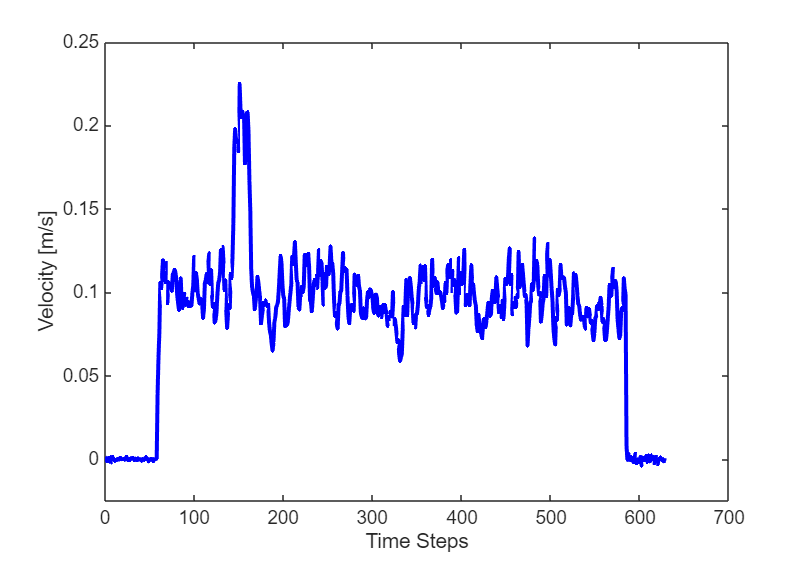

plot(odometry(:,3),'LineWidth',3,'Color','b'); % Plot with 3 line width
axis on
xlabel('Time Steps'); % Define x-axis label
ylabel('Velocity [m/s]'); % Define y-axis label
ylim([-0.025 0.25]);
set(gca,'FontName','Arial','FontSize',14); % Font for the plot

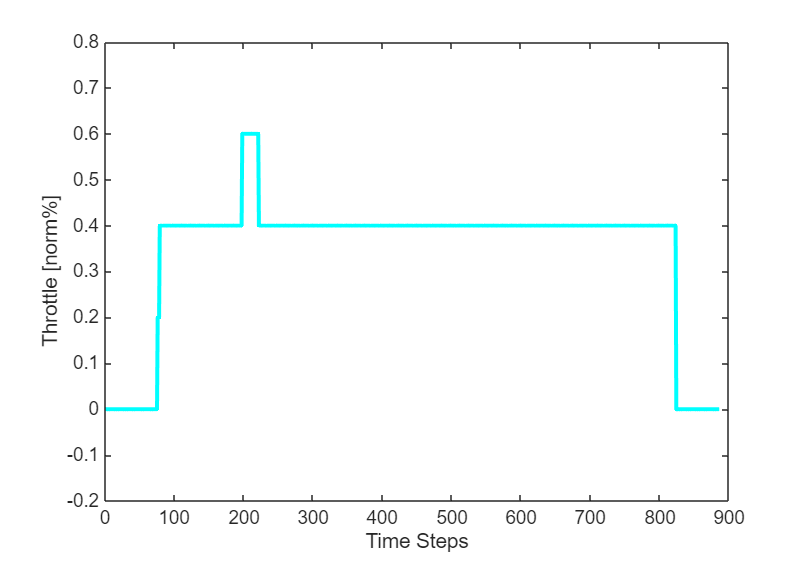

plot(throttle(:,1),'LineWidth',3,'Color','c'); % Plot with 3 line width
axis on
xlabel('Time Steps'); % Define x-axis label
ylabel('Throttle [norm%]'); % Define y-axis label
ylim([-0.2 0.8]);
set(gca,'FontName','Arial','FontSize',14); % Font for the plot

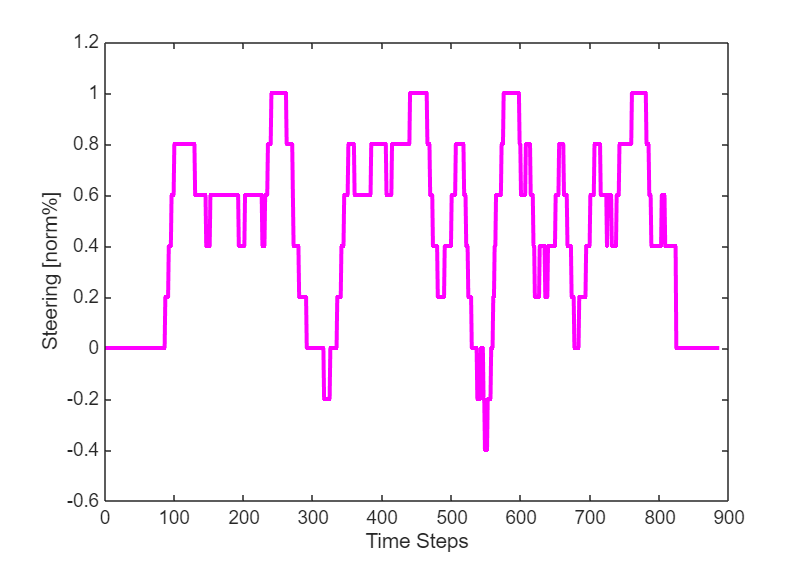

plot(steering(:,1),'LineWidth',3,'Color','m'); % Plot with 3 line width
axis on
xlabel('Time Steps'); % Define x-axis label
ylabel('Steering [norm%]'); % Define y-axis label
ylim([-0.6 1.2]);
set(gca,'FontName','Arial','FontSize',14); % Font for the plot

Save the data of interest to disk.

for i = 1:length(image_messages)
    image_index = sprintf('%04d',i) ;
    image_data = readImage(image_messages{i});    
    image_name = strcat(strcat(bag_file.FilePath(1:end-4)),'/',image_index,'.jpg');
    imwrite(image_data,image_name);
end
save(strcat(bag_file.FilePath(1:end-4),'.mat'), ...
    'odometry', ...
    'throttle', ...
    'steering');